# Dual-pixel autofocus sensor simulation

We illustrate how to create a dual pixel sensor for autofocus applications.  

The dual pixel design consists of a sensor with rectangular pixels that are twice as high as wide (see below).  There is a microlens over each pixel that directs light from the left half of the lens to the right pixel, and right half of the lens to the left pixel. This forms two independent images, seen through the right and left side of the lens.   

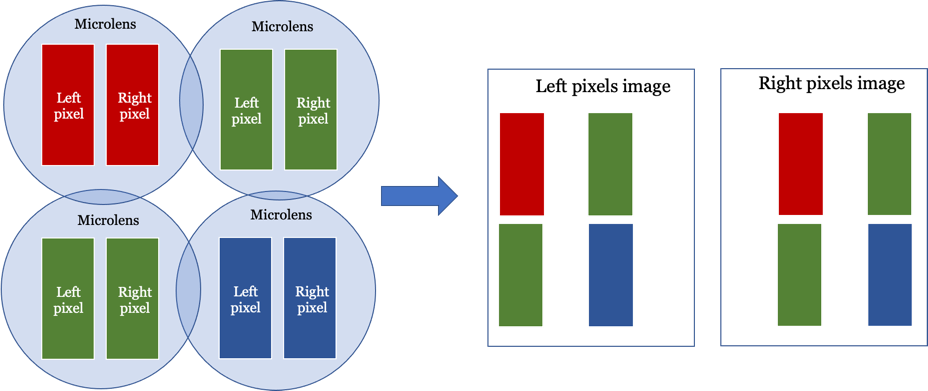

In regions where the focus is good, the left and right images have the same value.  But in regions where there is defocus, the left and right images do not have the same value.  

Using signal processing methods, we can detect the regions where the left and right image values are the same.  By adjusting the distance of the sensor from the lens, we make different regions in the left and right image match.  By choosing which regions match, we focusing that region of the image.

**See also:**

  s_sensorDPAF (ISETCam), tls_casmeraLightField.mlx

## Initialize

ieInit;
if ~piDockerExists, piDockerConfig; end
chdir(fullfile(piRootPath,'local'));

## Read the chess set scene

thisR = piRecipeDefault('scene name','chessSet');

Read 9 materials and 3 textures..


Put: rsync  --protocol=29  -e "ssh -x -T -o Compression=no" -r -t /Users/wandell/Documents/MATLAB/iset3d-v4/local/ChessSet/ wandell@muxreconrt.stanford.edu:/home/wandell/iset/iset3d-v4/local/ChessSet/ ...
Done (0.35 sec)
Command: docker --context remote-mux exec -it  pbrt-gpu-wandell4394 sh -c "cd /iset/iset3d-v4/local/ChessSet && rm -rf renderings/{*,.*}  && pbrt --gpu --outfile renderings/ChessSet.exr ChessSet.pbrt"
Rendered remotely in: 2.46 sec
Pull: rsync -r  wandell@muxreconrt.stanford.edu:/home/wandell/iset/iset3d-v4/local/ChessSet/renderings/ /Users/wandell/Documents/MATLAB/iset3d-v4/local/ChessSet/renderings ...
done (  0.37 sec)

Output file:  renderings/ChessSet.exr
*** Rendering time (ChessSet) was 3.9 sec ***



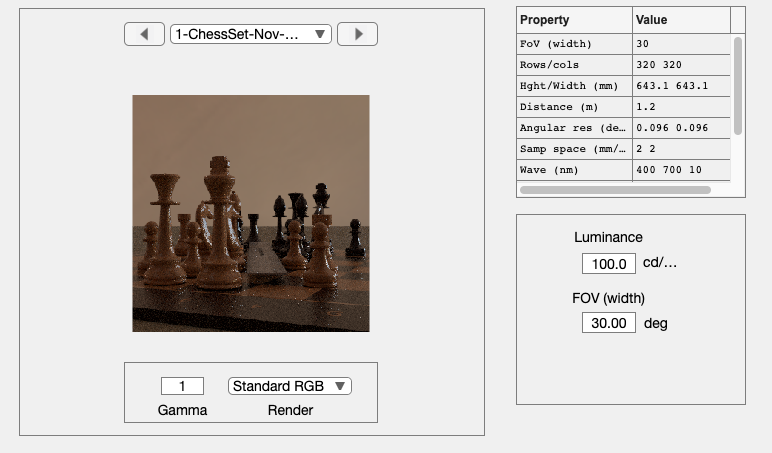

thisR.set('render type',{'radiance','depth'});
scene = piWRS(thisR);

dRange = sceneGet(scene,'depth range');   % Runs the docker to get the depth map

### Show just the imaging lens

iLensName = 'dgauss.22deg.3.0mm.json';  % Imaging lens
camera = piCameraCreate('omni','lens file',iLensName);
thisR.set('camera',camera);
thisR.set('film diagonal',4);
thisR.set('focus distance',2*dRange(2));

Put: rsync  --protocol=29  -e "ssh -x -T -o Compression=no" -r -t /Users/wandell/Documents/MATLAB/iset3d-v4/local/ChessSet/ wandell@muxreconrt.stanford.edu:/home/wandell/iset/iset3d-v4/local/ChessSet/ ...
Done (0.36 sec)
Command: docker --context remote-mux exec -it  pbrt-gpu-wandell4394 sh -c "cd /iset/iset3d-v4/local/ChessSet && rm -rf renderings/{*,.*}  && pbrt --gpu --outfile renderings/ChessSet.exr ChessSet.pbrt"
Rendered remotely in: 5.79 sec
Pull: rsync -r  wandell@muxreconrt.stanford.edu:/home/wandell/iset/iset3d-v4/local/ChessSet/renderings/ /Users/wandell/Documents/MATLAB/iset3d-v4/local/ChessSet/renderings ...
done (  0.47 sec)

Output file:  renderings/ChessSet.exr
*** Rendering time (ChessSet) was 7.3 sec ***



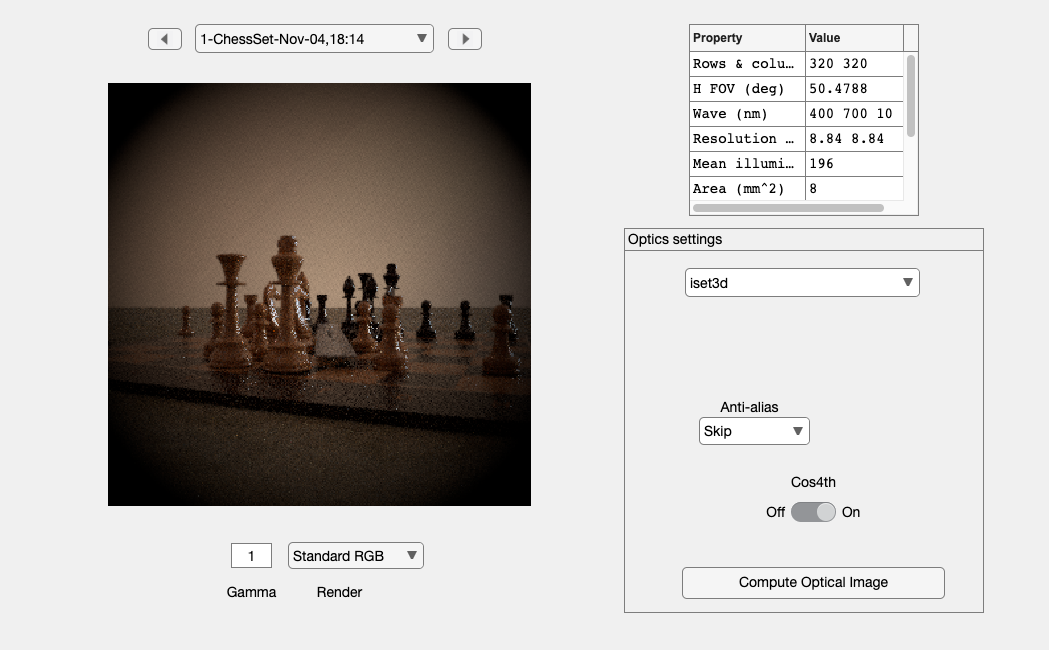

piWRS(thisR);

## Set up the combined imaging and microlens array

Make sure you have isetlens on your path!

uLensName = 'microlens.json';           % Microlens model

% The pixel width (below) is 1.4 um. The microlens covers two pixels
uLensDiameter = 0.0028;         % 2.8 um - each covers the dual pixels
nMicrolens    = 4*[128 128];      % There will be this many dual pixels

% This calls the docker container to create the combinedLensFile, which is
% a JSON description of the iLens and uLens.
[combinedLensFile, uLens, iLens] = lensCombine(uLensName,iLensName,uLensDiameter,nMicrolens);

Overwriting dgauss.22deg.3.0mm.json
Overwriting microlens.json

------
Microlens insertion summary
Microlens dimensions 512 512 
Microlens to film distance 0.005045
Film height and width 2.000000 2.000000
------
Imaging lens copy exists.  Not over-writing
Microlens copy exists.  Not over-writing
Status 0 (0 is good)
/Users/wandell/Documents/MATLAB/iset3d-v4/local/dgauss.22deg.3.0mm.json + /Users/wandell/Documents/MATLAB/iset3d-v4/local/microlens.json = /Users/wandell/Documents/MATLAB/iset3d-v4/local/dgauss.22deg.3.0mm+microlens.json




camera = piCameraCreate('omni','lensFile',combinedLensFile);
thisR.set('camera',camera);

## Set up the film parameters

We want the OI to have adequate spatial resolution.  We set it up here to calculate the irradiance at 4 positions for each microlens, and thus two positions for each of the pixels. The pair of up/down positions will be summed by the sensor into a single pixel response. The pair of left/right positions will be used to calculate the signal incident at the two pixels behind the microlens.

pixelsPerMicrolens = 2;
halfPixelWidth_mm = uLens.get('lens diameter')/pixelsPerMicrolens;    % mm

% The total film (sensor) size.
filmwidth  = nMicrolens(2)*uLens.get('diameter','mm');       % mm
filmheight = nMicrolens(1)*uLens.get('diameter','mm');       % mm
filmresolution = [filmheight, filmwidth]/halfPixelWidth_mm;

% This is the size of the film/sensor in millimeters
thisR.set('film diagonal',sqrt(filmwidth^2 + filmheight^2));

% Film resolution -
thisR.set('film resolution',filmresolution);

% The desired spacing is halfPixelWidth_mm 
assert(thisR.get('sample spacing') == halfPixelWidth_mm);

% This is the aperture of the imaging lens of the camera in mm
thisR.set('aperture diameter',10);

% Adjust for quality
thisR.set('rays per pixel',1024);


## Render

Write, render, and show the recipe.  The optical image is returned in oi.  We also confirm that the spatial samples in the oi will match the resolution of the sensor pixels.

Put: rsync  --protocol=29  -e "ssh -x -T -o Compression=no" -r -t /Users/wandell/Documents/MATLAB/iset3d-v4/local/ChessSet/ wandell@muxreconrt.stanford.edu:/home/wandell/iset/iset3d-v4/local/ChessSet/ ...
Done (0.53 sec)
Command: docker --context remote-mux exec -it  pbrt-gpu-wandell4394 sh -c "cd /iset/iset3d-v4/local/ChessSet && rm -rf renderings/{*,.*}  && pbrt --gpu --outfile renderings/ChessSet.exr ChessSet.pbrt"
Rendered remotely in: 50.06 sec
Pull: rsync -r  wandell@muxreconrt.stanford.edu:/home/wandell/iset/iset3d-v4/local/ChessSet/renderings/ /Users/wandell/Documents/MATLAB/iset3d-v4/local/ChessSet/renderings ...
done (  0.77 sec)

Output file:  renderings/ChessSet.exr
*** Rendering time (ChessSet) was 52.0 sec ***

Decoding lens parameters from lens file name /Users/wandell/Documents/MATLAB/iset3d-v4/local/dgauss.22deg.3.0mm+microlens.json


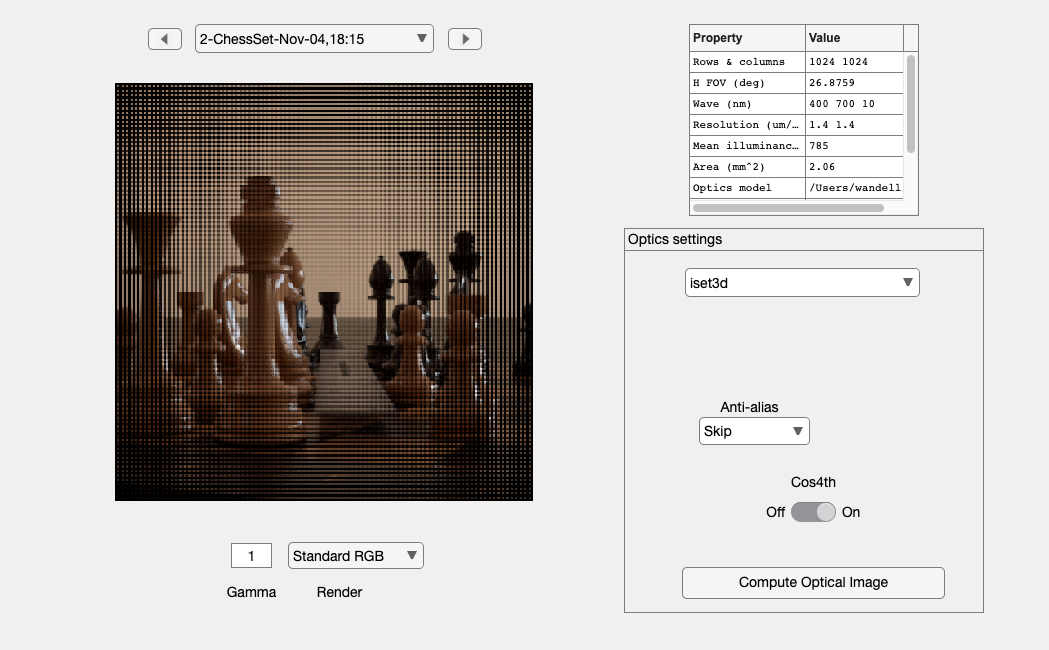

[oi, s] = piWRS(thisR);


ss = oiGet(oi,'sample spacing','mm');
assert(abs(ss(1) - halfPixelWidth_mm) < 10*eps);

## Make a dual pixel sensor that has rectangular pixels

sensor = sensorCreate('dual pixel',[],oi,nMicrolens);

## Compute the sensor data

Notice that we display the spatial structure of the image correctly, even though the pixels are rectangular.  That is magical programming behind the scene, where we know that the pixels are rectangular!

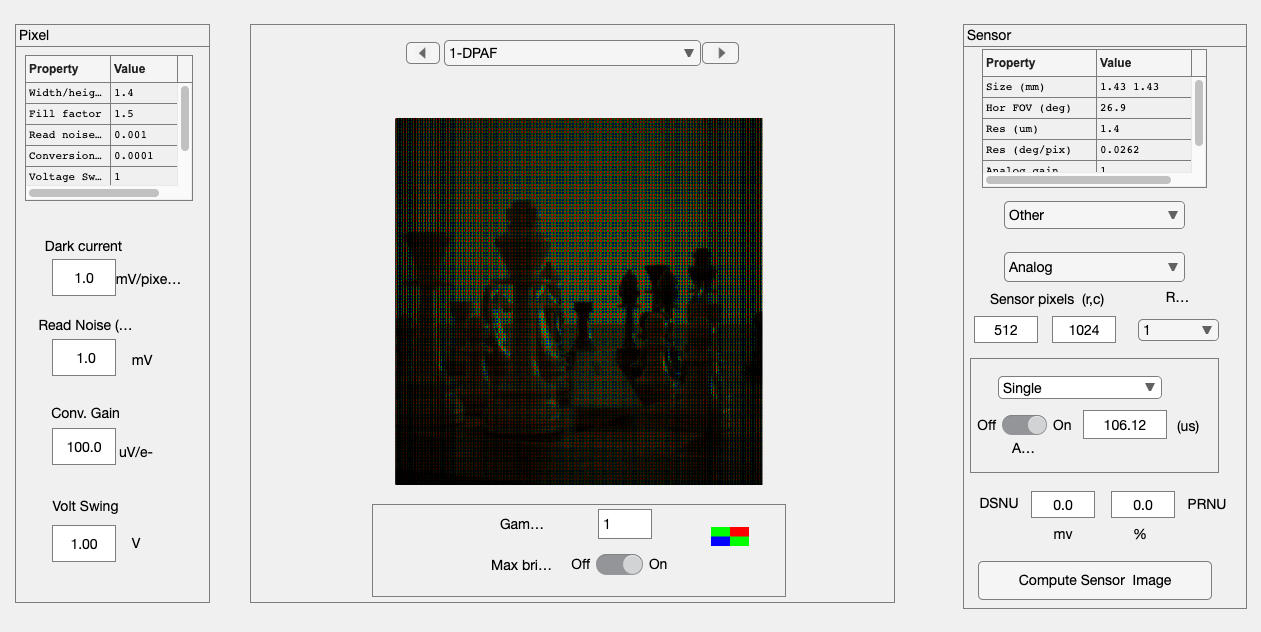

sensor = sensorCompute(sensor,oi);
sensor = sensorSet(sensor,'name','DPAF');
sensorWindow(sensor);

## Extract the left and right images from the dual pixel array

Every other pixel is left/right.

volts = sensorGet(sensor,'volts');
leftVolts = volts(1:end,1:2:end);
rightVolts = volts(1:end,2:2:end);

## Create sensors for left and right image

We take the left and right pixel voltages and place them into two different sensor structs.

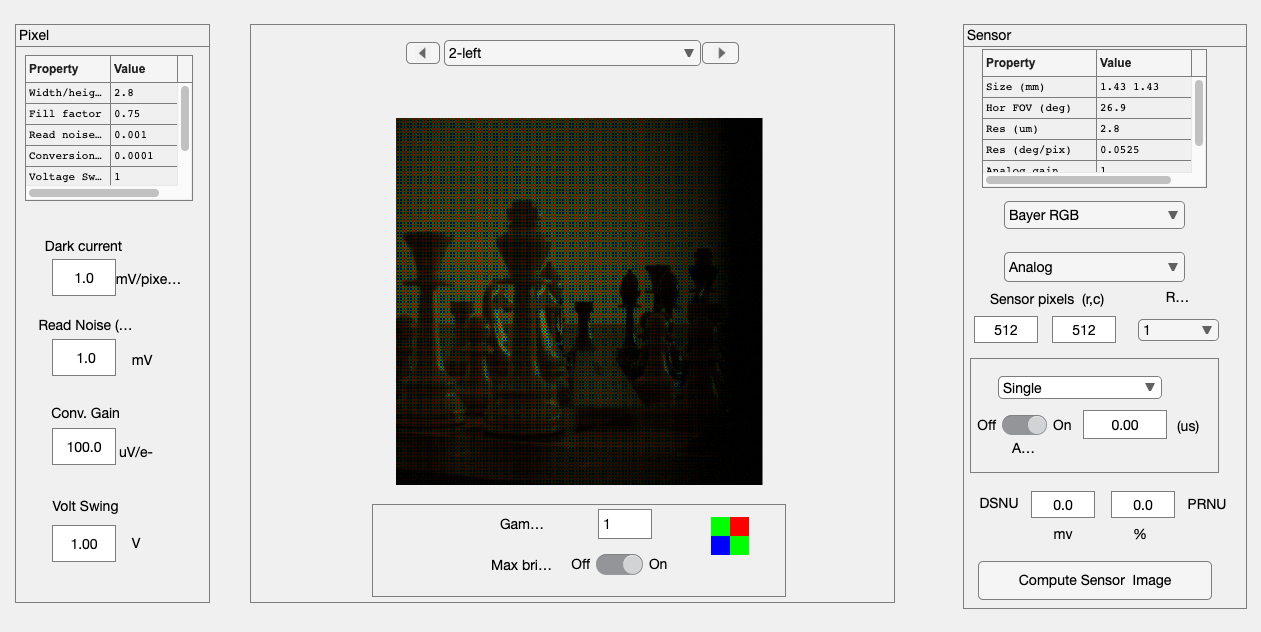

leftSensor = sensorCreate;
leftSensor = sensorSet(leftSensor,'size',size(leftVolts));
leftSensor = sensorSet(leftSensor,'volts',leftVolts);
leftSensor = sensorSet(leftSensor,'name','left');

sensorWindow(leftSensor);

## Now the right pixel voltages.

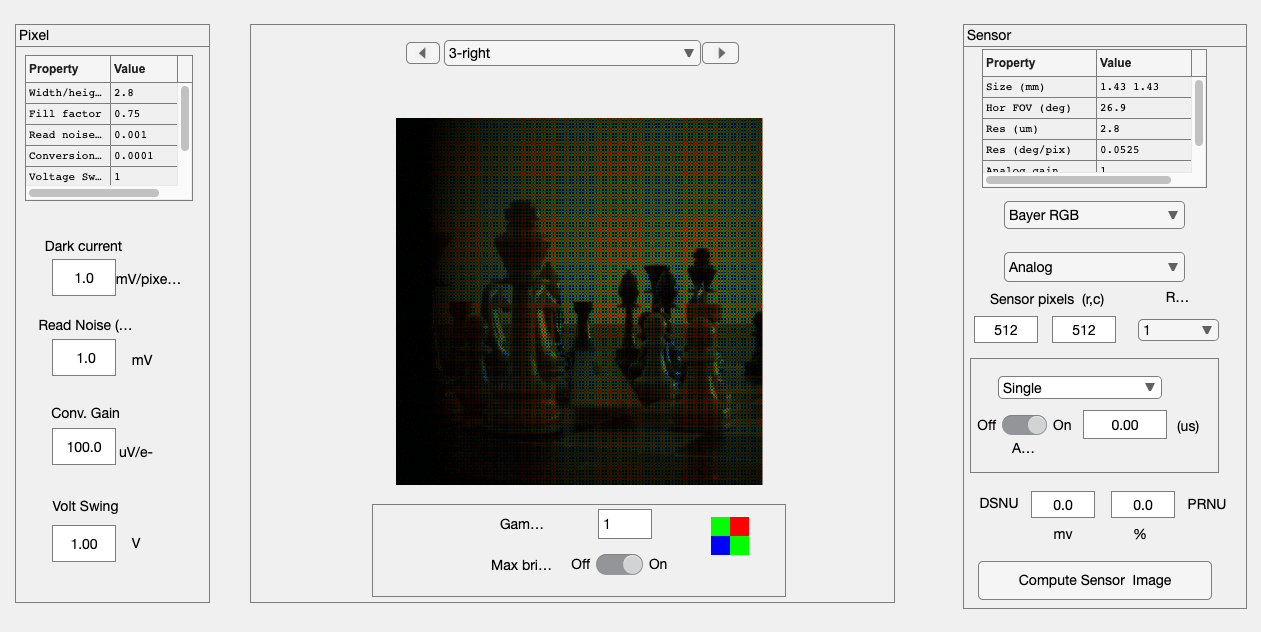

rightSensor = sensorCreate;
rightSensor = sensorSet(rightSensor,'size',size(rightVolts));
rightSensor = sensorSet(rightSensor,'volts',rightVolts);
rightSensor = sensorSet(rightSensor,'name','right');
sensorWindow(rightSensor);

### Plot lines through the left and right sensor data

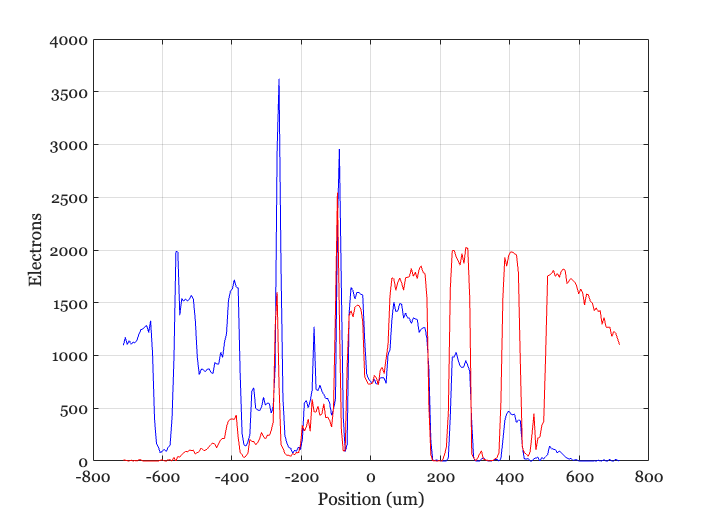

row = sensorGet(sensor,'row');
thisLine = round(row/2);  % The y-dimension

rightSensorData = sensorPlot(rightSensor,'electrons hline',[1 thisLine],'no fig', true);
leftSensorData  = sensorPlot(leftSensor,'electrons hline',[1 thisLine],'no fig',true);

ieNewGraphWin;
plot(leftSensorData.pos{1},leftSensorData.data{1},'b-',...
    rightSensorData.pos{1},rightSensorData.data{1},'r-');
grid on; xlabel('Position (um)'); ylabel('Electrons');

### Sum the left and right and make an image

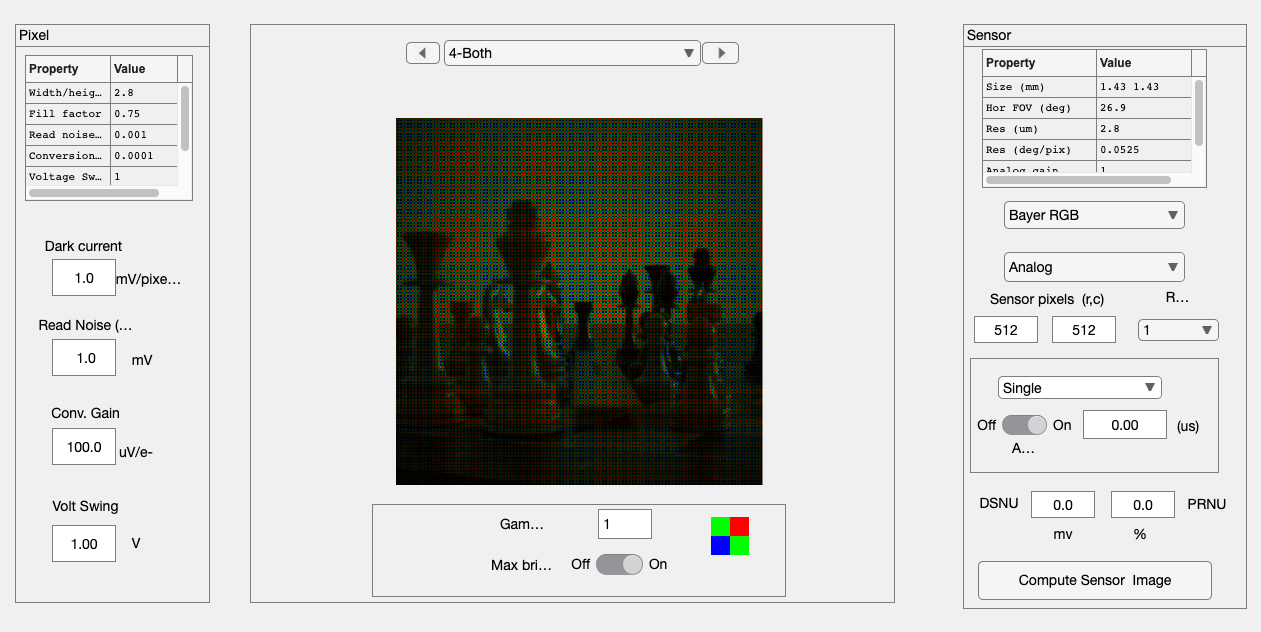

bothVolts = (leftVolts + rightVolts)/2;

sensorBoth = rightSensor;
sensorBoth = sensorSet(sensorBoth,'volts',bothVolts);
sensorBoth = sensorSet(sensorBoth,'name','Both');
sensorWindow(sensorBoth);

### Create an image processor view of the sum

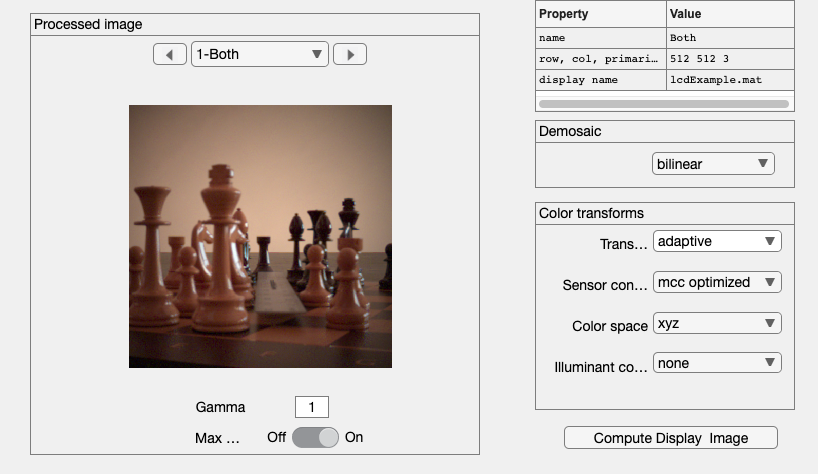

ipBoth = ipCreate;
ipBoth = ipCompute(ipBoth,sensorBoth);
ipWindow(ipBoth);

### Compare the left and right image views 

leftip = ipCreate;
leftip = ipCompute(leftip,leftSensor);
ipWindow(leftip);

#### Get data from the left image

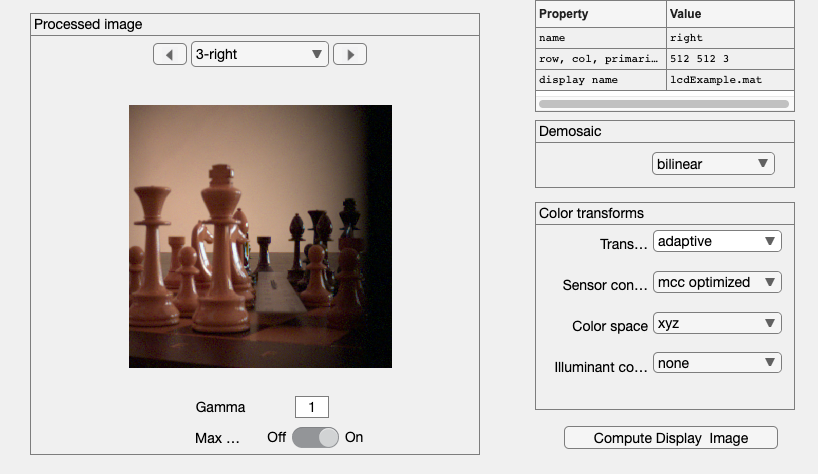

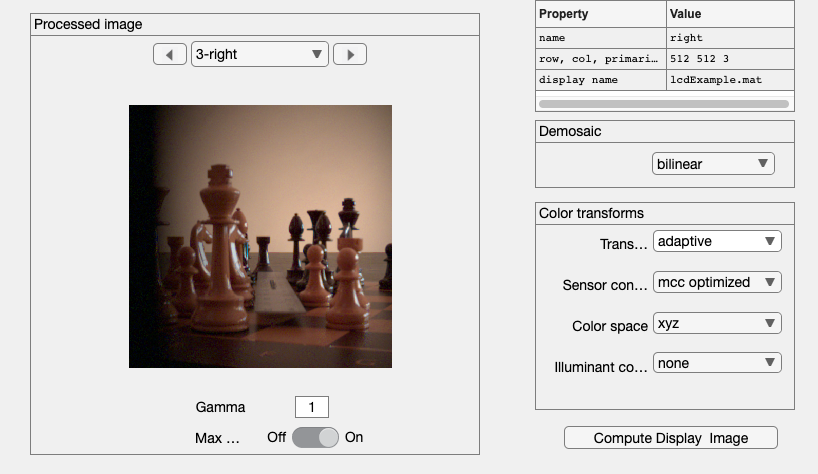

rightip = ipCreate;
rightip = ipCompute(rightip,rightSensor);
ipWindow(rightip);

#### END